# 1. How finite should it be

#### 1.1 Like a hot knive through a Butterworth

pb = [0.2 0.3];
sb = [0.1 0.4];
rp = 2;
Gs = 100;

[n,wn] = cheb1ord(pb,sb,rp,Gs);

[b,a] = cheby1(n,rp,pb,"bandpass");

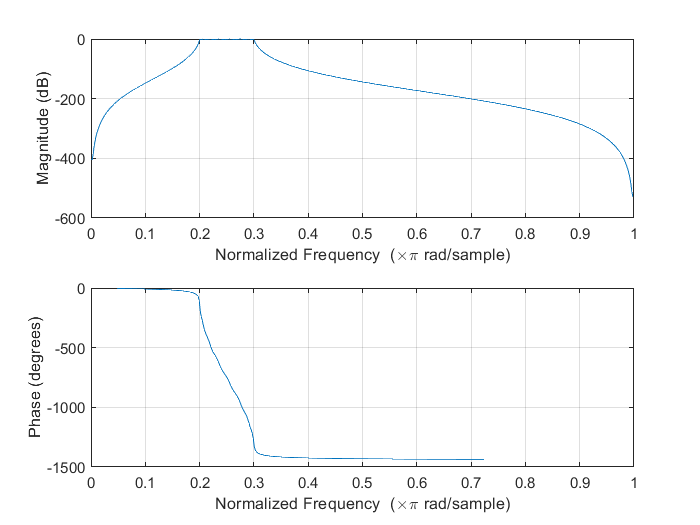

freqz(b,a)

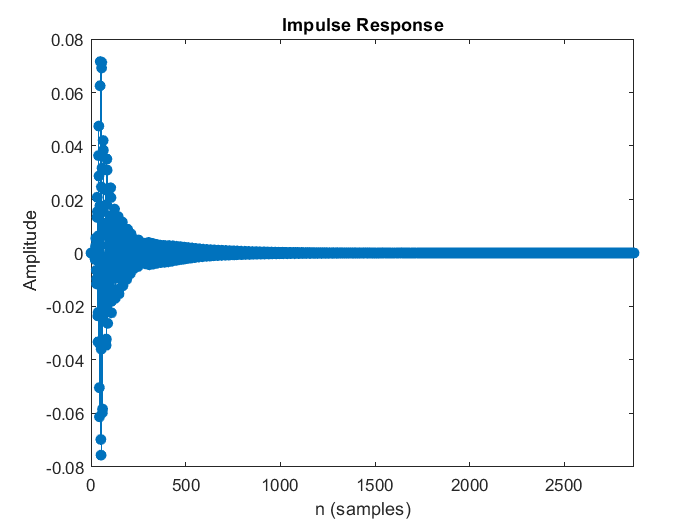

impz(b,a)

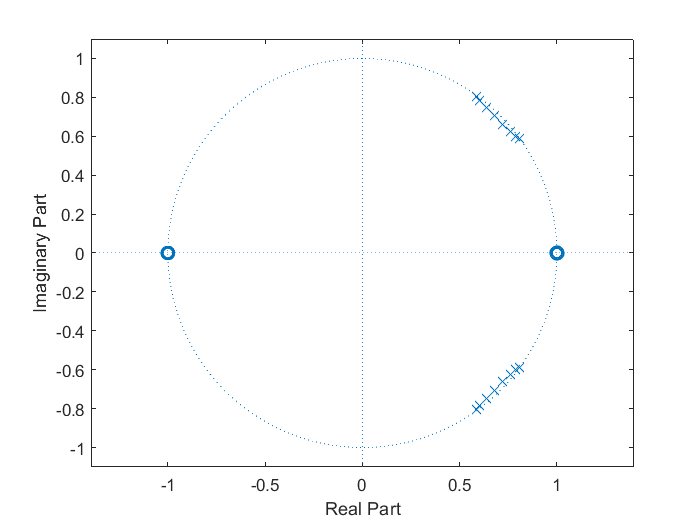

zplane(b,a)

[h,t]  = impz(b,a);
el = find(h > (max(h) * 0.1), 1, 'last')

el = 194

h_ef = h(1:el);
h_75 = h(1:fix(0.75*el));
h_60 = h(1:fix(0.6*el));
h_40 = h(1:fix(0.4*el));
h_10 = h(1:fix(0.1*el));

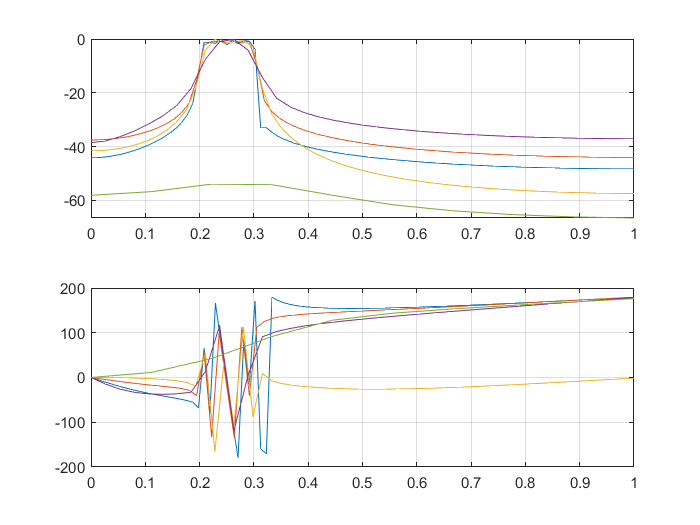

[ef.w,ef.a,ef.p] = makeNormSpec(h_ef);
[e75.w,e75.a,e75.p] = makeNormSpec(h_75);
[e60.w,e60.a,e60.p] = makeNormSpec(h_60);
[e40.w,e40.a,e40.p] = makeNormSpec(h_40);
[e10.w,e10.a,e10.p] = makeNormSpec(h_10);

figure(); subplot(2,1,1); plot(ef.w,ef.a); grid on; hold on; plot(e75.w,e75.a); plot(e60.w,e60.a); plot(e40.w,e40.a); plot(e10.w,e10.a); hold off;
subplot(2,1,2); plot(ef.w,ef.p); grid on; hold on; plot(e75.w,e75.p); plot(e60.w,e60.p); plot(e40.w,e40.p); plot(e10.w,e10.p); hold off;

#### 1.2 Shorter and shorter


$$f_s = 30\;\text{kHz}$$


fs = 30e3;
T = 601/fs

T = 0.0200

delta_f = 1/T

delta_f = 49.9168

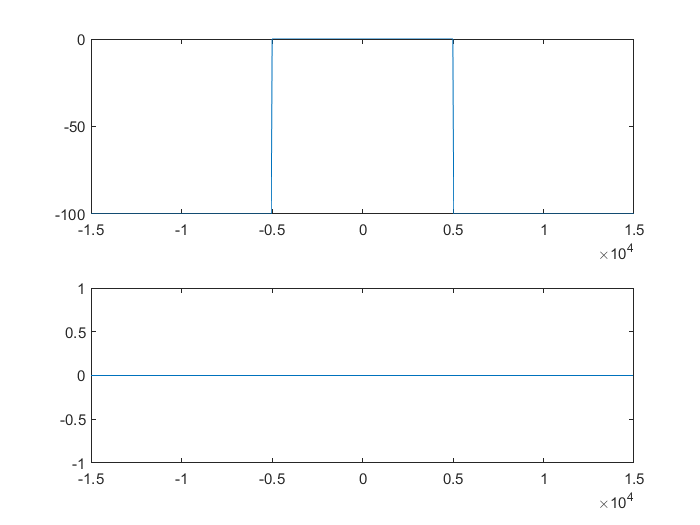

f = 0:delta_f:(fs/2);
Y = 0.00001*ones(1,length(f));
for i = 1:ceil(length(f)/3)
    Y(i) = 1;
end
f = [-flip(f) f(2:end)];
Y = [flip(Y) Y(2:end)];
figure();
subplot(2,1,1); plot(f,20*log10(abs(Y)));
subplot(2,1,2); plot(f,angle(Y)*180/pi);

h = ifft(ifftshift(Y));
t = 0:(1/fs):(T-1/fs);
length(t)

ans = 601

length(h)

ans = 601

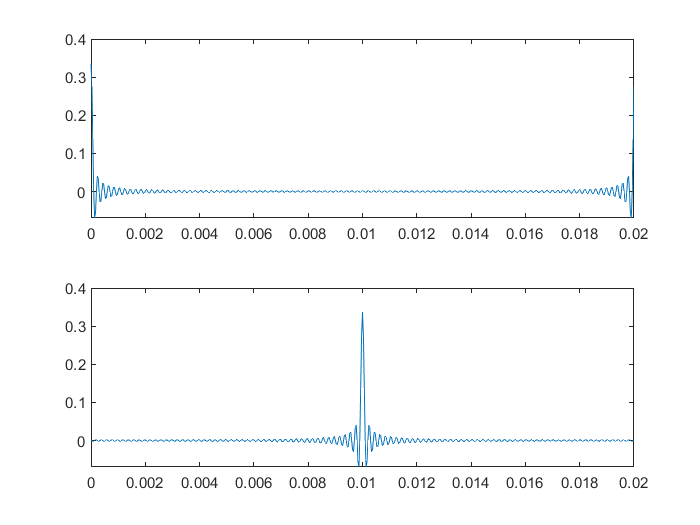

figure(); subplot(2,1,1); plot(t,h);
subplot(2,1,2); plot(t,fftshift(h))

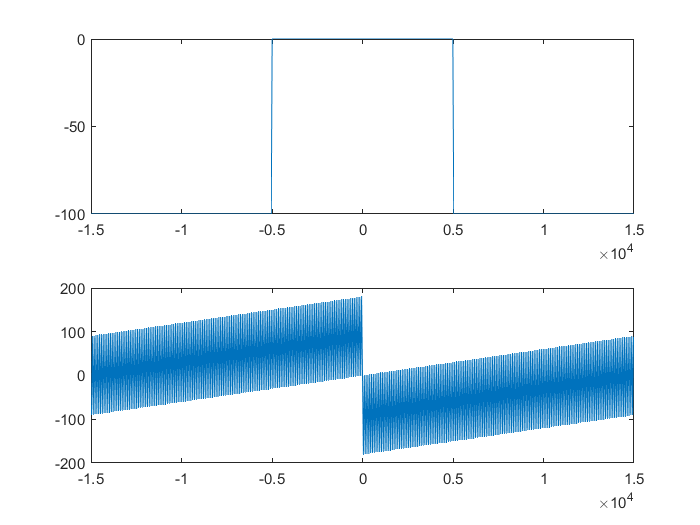

Y2 = fftshift(fft(fftshift(h)));
figure();
subplot(2,1,1); plot(f,20*log10(abs(Y2)));
subplot(2,1,2); plot(f,angle(Y2)*180/pi);

# 2. An equalizer - without buttons

#### 2.1 Bass and treble

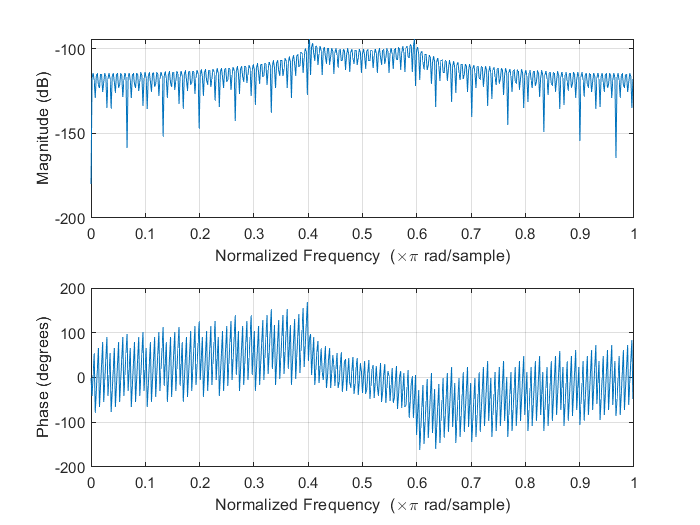

[b,a] = FirBandpass(... % the future is now old man
0.4062,...
0.5979, ...
  -100, ...
  377);

freqz(b,a)

function [b,a] = FirBandpass(wc_lwr,wc_upr,G,L)
    idx_lwr = fix(wc_lwr*L);
    idx_upr = fix(wc_upr*L);
    Y = 0.000000001*ones(1,L);
    for i = idx_lwr:idx_upr
        Y(i) = 10^(G/20);
    end
    Y = [flip(Y) Y(2:end)];
    h = ifft(ifftshift(Y));
    b=h;
    a=[1];
end
function [w,amp,phase] = makeNormSpec(h)
    y = fft(h);
    y = y(1:ceil(length(y)/2));
    w = linspace(0,1,length(y));
    amp = 20*log10(abs(y));
    phase = angle(y)*180/pi;
end